clear;
clc;
mpc = case33open_new;
V_base = 10;	
lambda_base=mpc.gen(1,6);

P=mpc.bus(:,3);
N=size(P,1);
% path-branch incidence matrix
branch_info=mpc.branch(:,1:2);
P_bus=P(2:N,:);

[H] = gen_path_branch(branch_info,N);
H_modified=H(:,2:N);
R_branch=diag(mpc.branch(:,3));

**With DG**

G_loc=[25,28,31];
G_power=[0.66,0.6,0.67];
switch_1=[25   16   0.1522];
switch_2=[31   13   0.1204];
switch_3=[28   10   0.1330];

P_copy =P;
for i=1:size(G_loc,2)
    loc=G_loc(i);
    power=G_power(i);
   P_copy(loc)= P_copy(loc)-power;
end
P_bus_new=P_copy(2:N,:);
LFP_new=2.*H_modified'*R_branch*H_modified*P_bus_new./V_base.^2;
for i=1:size(G_loc,2)
    loc=G_loc(i)-1;
    disp(LFP_new(loc))
end

    0.0177

    0.0328

    0.0285



disp(LFP_new(1))

    0.0033



LMP_3=(1+[0;LFP_new])*lambda_base;

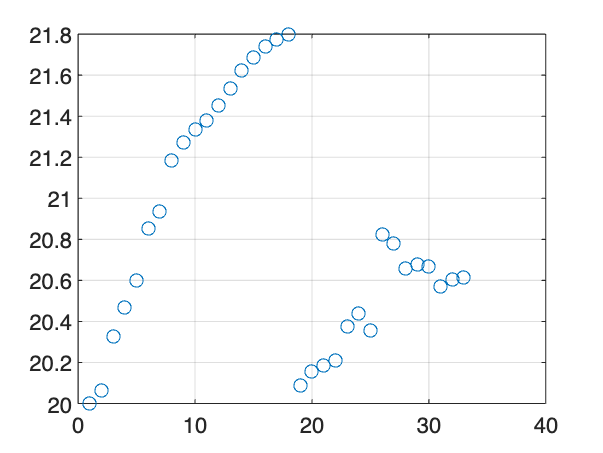

figure
plot(1:N,LMP_3,'o')
grid on

ini_bid=zeros(size(G_loc,2),1);
for i=1:size(G_loc,2)
    loc=G_loc(i);
    ini_bid(i)=LMP_3(loc);
end
disp(ini_bid)

   20.3545
   20.6555
   20.5704



[ini_bid_sort, order]=sort(ini_bid);

**First ETM : bus 25**

% disp(LMP_3(16:18))
H_1=triu(ones(3));
P_1=P(16:18,:);
branch_needed=[switch_1(3),mpc.branch(16,3),mpc.branch(17,3) ];
R_branch_1=diag(branch_needed);
% disp(R_branch_1)
LFP_new=H_1'*R_branch_1*H_1*P_1./V_base.^2;
disp(LMP_3(16:18)./(1+LFP_new))

   21.7329
   21.7490
   21.7594




loss=(H_1*P_1)'*R_branch_1*H_1*P_1./V_base.^2;
P_base=sum(P(16:18));
xx_pre=0:0.005:P_base+loss;
A_lambda_max=ones(1, size(xx_pre,2))*min(LMP_3(16:18)./(1+LFP_new));
mark_x=P_base+loss;
mark_y=min(LMP_3(16:18)./(1+LFP_new));

unit_break=[0];
k=0;
LMP_ori=LMP_3(16:18);
add_load_unit=0;
incre=0.002;
%A_lambda_max=[];
loss_record=[];
for ii=15:-1:12
    k=k+1;
    loc=ii;
    branch_needed=[branch_needed,mpc.branch(loc,3)];
    R_branch_1=diag(branch_needed);
    P_1=[P_1;P(loc)];
    P_1_loc=P_1;
    H_1=[H_1;zeros(1,k+2)];
    H_1=[H_1 zeros(k+3,1)];
    H_1(1,k+3)=1;
    for mm=4:k+3
        H_1(mm,k+3)=1;
    end
    %disp(H_1)
    LMP_ori=[LMP_ori;LMP_3(loc)];
    for xx=0:incre:P(loc) 
        P_1_loc(3+k)=xx;
        LFP_new=H_1'*R_branch_1*H_1*P_1_loc./V_base.^2;
%         disp(loc)
%         disp(LFP_new')
%         disp((LMP_ori./(1+LFP_new))')
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H_1*P_1_loc)'*R_branch_1*H_1*P_1_loc./V_base.^2;
        loss_record=[loss_record,loss];
        if xx==0
            mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
            mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
        end
    end
    mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
    mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
    unit_break=[unit_break,add_load_unit-k];
end

**plot**

xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj):unit_break(jj+1)];
end
xx=P_base+xx*incre+loss_record;
xx_new=[xx_pre,xx];
y_min=ones(1,size(xx_new,2))*ini_bid_sort(1);
loc=G_loc(order(1));
surplus_1=G_power(order(1))-P(25);
index=find(xx_new>surplus_1,1)-1;
% display(xx_new(index))
% display(surplus_1-xx_new(index))
% final price
final_price_1=(A_lambda_max(index+1)+ini_bid_sort(1))/2;
Final_price_1=round(final_price_1,2);
% BREAK POINT
% corresponding
aaa=1:size(unit_break,2);
aaa=ceil(aaa/2);
unit_break_2=unit_break+aaa+size(xx_pre,2);
real_p_break=xx_new(unit_break_2);
% find how much of 15 is convered by gen 25
break_index=1;
amount=surplus_1-real_p_break(break_index);
display(amount)

amount = 0.0297

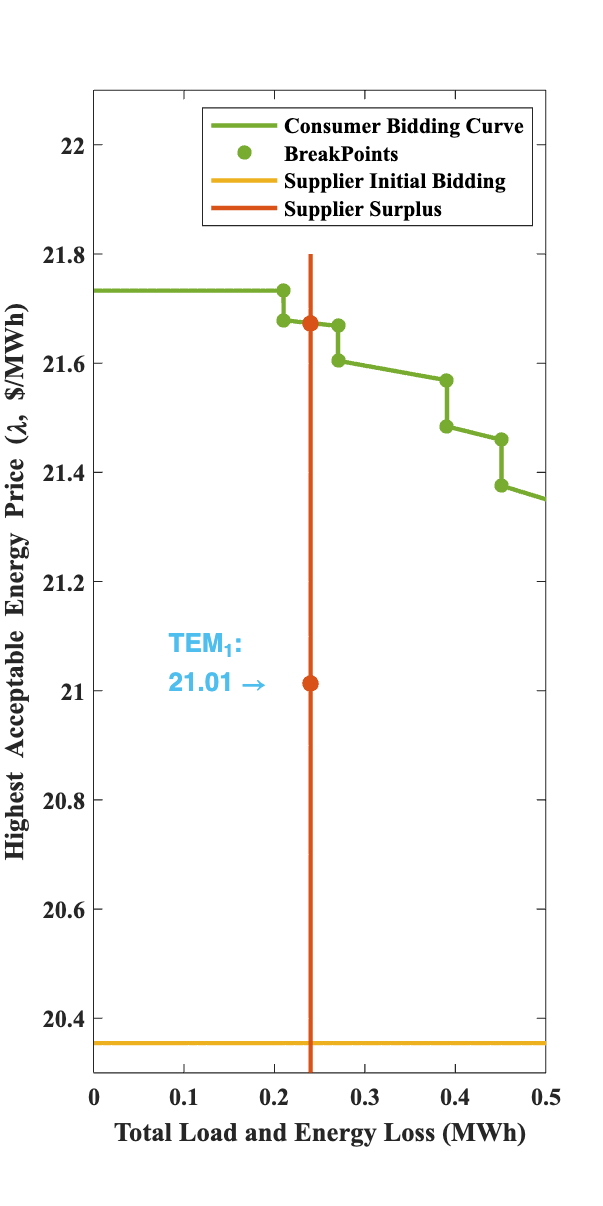

mark_loc=A_lambda_max(index+1);



y_end=round(max(mark_y),1)+0.1;
y_begin=round(ini_bid_sort(1),1)-0.1;
y_hor=y_begin:0.1:y_end;
x_hor=ones(1, size(y_hor,2))*surplus_1;

price_str=[num2str(Final_price_1),'\rightarrow'];

figure
plot(xx_new, A_lambda_max,'LineWidth',2,'Color',[0.4660, 0.6740, 0.1880])
ylim([y_begin,22.1])
xlim([0,0.5])
hold on
plot(mark_x,mark_y,'o', 'markersize', 6,'MarkerFaceColor',[0.4660, 0.6740, 0.1880],'MarkerEdgeColor',[0.4660, 0.6740, 0.1880])
hold on 
plot(xx_new, y_min,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
hold on 
plot(x_hor,y_hor,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_1,mark_loc,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_1,final_price_1,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
t=text(surplus_1-0.16,final_price_1,price_str);
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';
t=text(surplus_1-0.16,final_price_1+0.07,'TEM_1:');
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';

legend('Consumer Bidding Curve','BreakPoints','Supplier Initial Bidding','Supplier Surplus')
xlabel('Total Load and Energy Loss (MWh)')
ylabel('Highest Acceptable Energy Price (\lambda, $/MWh)')
set(gcf,'Position',[100 100 300 600]);
set(gca,'FontSize',11,'FontName','Times New Roman','FontWeight','Bold')

% figure
% plot(1:add_load_unit,loss_record)
% final price for every one
P_1=[P(16:18,:);amount];
H_1=triu(ones(3));
H_1=[H_1;zeros(1,3)];
H_1=[H_1 zeros(4,1)];
H_1(1,4)=1;
H_1(4,4)=1;
branch_needed=[switch_1(3),mpc.branch(16,3),mpc.branch(17,3),mpc.branch(15,3) ];
R_branch_1=diag(branch_needed);
% disp(R_branch_1)
LFP_new=H_1'*R_branch_1*H_1*P_1./V_base.^2;
price_new=(1+LFP_new).*final_price_1;
LMP_ori=[LMP_3(16:18);LMP_3(15)];

display('16,17,18,15')

16,17,18,15


display(LMP_ori')

   21.7399   21.7752   21.7979   21.6856



display(price_new')

   21.0216   21.0402   21.0522   21.0257



display(((LMP_ori-price_new)./LMP_ori*100)')

    3.3037    3.3754    3.4214    3.0430



display( ini_bid_sort(1))

   20.3545



display((final_price_1-ini_bid_sort(1))/ini_bid_sort(1)*100)

    3.2400



**ETM 2: bus 31 **

disp(LMP_3(13:15))

   21.5372
   21.6217
   21.6856



H_2=triu(ones(3));
P_2=P(13:15,:);
P_2(3)=P_2(3)-amount;
P_2_record=P_2;
branch_needed=[switch_2(3),mpc.branch(13,3),mpc.branch(14,3) ];
R_branch_2=diag(branch_needed);
% disp(R_branch_1)
LFP_new=H_2'*R_branch_2*H_2*P_2./V_base.^2;
disp(LMP_3(13:15)./(1+LFP_new))

   21.5318
   21.5987
   21.6586




loss=(H_2*P_2)'*R_branch_2*H_2*P_2./V_base.^2;
P_base=sum(P_2);
xx_pre=0:0.005:P_base+loss;
A_lambda_max=ones(1, size(xx_pre,2))*min(LMP_3(13:15)./(1+LFP_new));
mark_x=P_base+loss;
mark_y=min(LMP_3(13:15)./(1+LFP_new));

unit_break=[0];
k=0;
LMP_ori=LMP_3(13:15);
add_load_unit=0;
incre=0.002;
%A_lambda_max=[];
loss_record=[];
for ii=12:-1:10
    k=k+1;
    loc=ii;
    branch_needed=[branch_needed,mpc.branch(loc,3)];
    R_branch_2=diag(branch_needed);
    P_2=[P_2;P(loc)];
    P_2_loc=P_2;
    H_2=[H_2;zeros(1,k+2)];
    H_2=[H_2 zeros(k+3,1)];
    H_2(1,k+3)=1;
    for mm=4:k+3
        H_2(mm,k+3)=1;
    end
%     disp(H_2)
    LMP_ori=[LMP_ori;LMP_3(loc)];
    for xx=0:incre:P(loc) 
        P_2_loc(3+k)=xx;
        LFP_new=H_2'*R_branch_2*H_2*P_2_loc./V_base.^2;
%         disp(loc)
%         disp(LFP_new')
%         disp((LMP_ori./(1+LFP_new))')
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H_2*P_2_loc)'*R_branch_2*H_2*P_2_loc./V_base.^2;
        loss_record=[loss_record,loss];
        if xx==0
            mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
            mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
        end
    end
    mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
    mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
    unit_break=[unit_break,add_load_unit-k];
end

**plot**

xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj):unit_break(jj+1)];
end
xx=P_base+xx*incre+loss_record;
xx_new=[xx_pre,xx];
y_min=ones(1,size(xx_new,2))*ini_bid_sort(2);
loc=G_loc(order(2));
H_self=[1 1; 0 1];
R_self=diag([mpc.branch(31,3),mpc.branch(32,3)]);
P_self=[P(32);P(33)];
loss_self=(H_self*P_self)'*R_self*H_self*P_self./V_base.^2;
surplus_2=G_power(order(2))-P(31)-P(32)-P(33)-loss_self;
index=find(xx_new>surplus_2,1)-1;
% display(xx_new(index))
% display(surplus_2-xx_new(index))
% final price
final_price_2=(A_lambda_max(index+1)+ini_bid_sort(2))/2;
Final_price_2=round(final_price_2,2);
% BREAK POINT
% corresponding
aaa=1:size(unit_break,2);
aaa=ceil(aaa/2);
unit_break_2=unit_break+aaa+size(xx_pre,2);
real_p_break=xx_new(unit_break_2);
% find how much of 12 is convered by gen 31
break_index=1;
amount=surplus_2-real_p_break(break_index);
display(amount)

amount = 0.0393

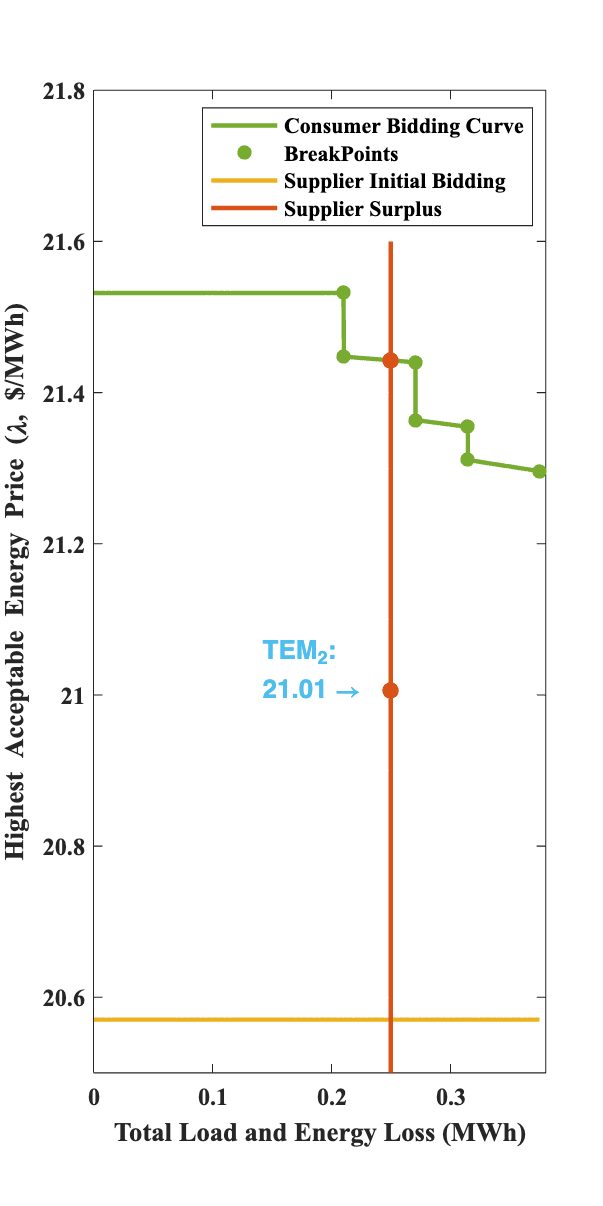

mark_loc=A_lambda_max(index+1);

y_end=round(max(mark_y),1)+0.1;
y_begin=round(ini_bid_sort(2),1)-0.1;
y_hor=y_begin:0.1:y_end;
x_hor=ones(1, size(y_hor,2))*surplus_2;

price_str=[num2str(Final_price_2),'\rightarrow'];

figure
plot(xx_new, A_lambda_max,'LineWidth',2,'Color',[0.4660, 0.6740, 0.1880])
ylim([y_begin, 21.8])
xlim([0, 0.38])
hold on
plot(mark_x,mark_y,'o', 'markersize', 6,'MarkerFaceColor',[0.4660, 0.6740, 0.1880],'MarkerEdgeColor',[0.4660, 0.6740, 0.1880])
hold on 
plot(xx_new, y_min,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
hold on 
plot(x_hor,y_hor,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_2,mark_loc,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_2,final_price_2,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
t=text(surplus_2-0.11,final_price_2,price_str);
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';
t=text(surplus_2-0.11,final_price_2+0.05,'TEM_2:');
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';

legend('Consumer Bidding Curve','BreakPoints','Supplier Initial Bidding','Supplier Surplus')
xlabel('Total Load and Energy Loss (MWh)')
ylabel('Highest Acceptable Energy Price (\lambda, $/MWh)')
set(gcf,'Position',[100 100 300 600]);
set(gca,'FontSize',11,'FontName','Times New Roman','FontWeight','Bold')

% final price for every one
P_2=[P_2_record;amount];
H_2=triu(ones(3));
H_2=[H_2;zeros(1,3)];
H_2=[H_2 zeros(4,1)];
H_2(1,4)=1;
H_2(4,4)=1;
branch_needed=[switch_2(3),mpc.branch(13,3),mpc.branch(14,3),mpc.branch(12,3) ];
R_branch_2=diag(branch_needed);
% disp(R_branch_2)
LFP_new=H_2'*R_branch_2*H_2*P_2./V_base.^2;
price_new=(1+LFP_new).*final_price_2;
LMP_ori=[LMP_3(13:15);LMP_3(12)];

display('13,14,15,12')

13,14,15,12


display(LMP_ori')

   21.5372   21.6217   21.6856   21.4530



display(price_new')

   21.0128   21.0299   21.0336   21.0166



display(((LMP_ori-price_new)./LMP_ori*100)')

    2.4352    2.7374    3.0064    2.0341



display( ini_bid_sort(2))

   20.5704



display((final_price_2-ini_bid_sort(2))/ini_bid_sort(2)*100)

    2.1199



**ETM 3: bus 28**

disp(LMP_3(10:12))

   21.3330
   21.3766
   21.4530



H_3=triu(ones(3));
P_3=P(10:12,:);
P_3(3)=P_3(3)-amount;
P_3_record=P_3;
branch_needed=[switch_3(3),mpc.branch(10,3),mpc.branch(11,3) ];
R_branch_3=diag(branch_needed);
% disp(R_branch_3)
LFP_new=H_3'*R_branch_3*H_3*P_3./V_base.^2;
disp(LMP_3(10:12)./(1+LFP_new))

   21.3294
   21.3703
   21.4450




loss=(H_3*P_3)'*R_branch_3*H_3*P_3./V_base.^2;
P_base=sum(P_3);
xx_pre=0:0.005:P_base+loss;
A_lambda_max=ones(1, size(xx_pre,2))*min(LMP_3(10:12)./(1+LFP_new));
mark_x=P_base+loss;
mark_y=min(LMP_3(10:12)./(1+LFP_new));

unit_break=[0];
k=0;
LMP_ori=LMP_3(10:12);
add_load_unit=0;
incre=0.002;
%A_lambda_max=[];
loss_record=[];
for ii=9:-1:7
    k=k+1;
    loc=ii;
    branch_needed=[branch_needed,mpc.branch(loc,3)];
    R_branch_3=diag(branch_needed);
    P_3=[P_3;P(loc)];
    P_3_loc=P_3;
    H_3=[H_3;zeros(1,k+2)];
    H_3=[H_3 zeros(k+3,1)];
    H_3(1,k+3)=1;
    for mm=4:k+3
        H_3(mm,k+3)=1;
    end
%     disp(H_3)
    LMP_ori=[LMP_ori;LMP_3(loc)];
    for xx=0:incre:P(loc) 
        P_3_loc(3+k)=xx;
        LFP_new=H_3'*R_branch_3*H_3*P_3_loc./V_base.^2;
%         disp(loc)
%         disp(LFP_new')
%         disp((LMP_ori./(1+LFP_new))')
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H_3*P_3_loc)'*R_branch_3*H_3*P_3_loc./V_base.^2;
        loss_record=[loss_record,loss];
        if xx==0
            mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
            mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
        end
    end
    mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
    mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
    unit_break=[unit_break,add_load_unit-k];
end

**plot**

xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj):unit_break(jj+1)];
end
xx=P_base+xx*incre+loss_record;
xx_new=[xx_pre,xx];
y_min=ones(1,size(xx_new,2))*ini_bid_sort(3);
loc=G_loc(order(3));
H_self=[1 1; 0 1];
R_self=diag([mpc.branch(28,3),mpc.branch(29,3)]);
P_self=[P(29);P(30)];
loss_self=(H_self*P_self)'*R_self*H_self*P_self./V_base.^2;
surplus_3=G_power(order(3))-P(28)-P(29)-P(30)-loss_self;
index=find(xx_new>surplus_3,1)-1;
% display(xx_new(index))
% display(surplus_2-xx_new(index))
% final price
final_price_3=(A_lambda_max(index+1)+ini_bid_sort(3))/2;
mark_loc=A_lambda_max(index+1);
Final_price_3=round(final_price_3,2);


% BREAK POINT
% corresponding
aaa=1:size(unit_break,2);
aaa=ceil(aaa/2);
unit_break_2=unit_break+aaa+size(xx_pre,2);
real_p_break=xx_new(unit_break_2);
% find how much of 8 is convered by gen 28
break_index=2;
amount=surplus_3-real_p_break(break_index);
display(amount)

amount = 0.0332

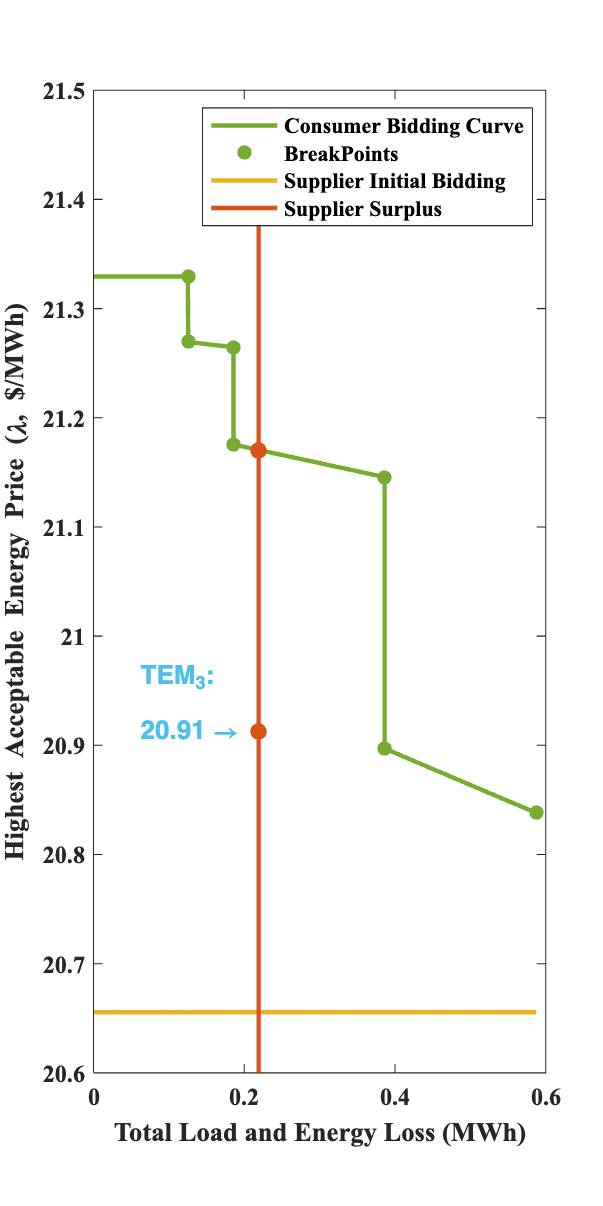



y_end=round(max(mark_y),1)+0.1;
y_begin=round(ini_bid_sort(3),1)-0.1;
y_hor=y_begin:0.1:y_end;
x_hor=ones(1, size(y_hor,2))*surplus_3;

price_str=[num2str(Final_price_3),'\rightarrow'];

figure
plot(xx_new, A_lambda_max,'LineWidth',2,'Color',[0.4660, 0.6740, 0.1880])
ylim([y_begin, 21.5])
hold on
plot(mark_x,mark_y,'o', 'markersize', 6,'MarkerFaceColor',[0.4660, 0.6740, 0.1880],'MarkerEdgeColor',[0.4660, 0.6740, 0.1880])
hold on 
plot(xx_new, y_min,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
hold on 
plot(x_hor,y_hor,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_3,mark_loc,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_3,final_price_3,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
t=text(surplus_3-0.16,final_price_3,price_str);
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';
t=text(surplus_3-0.16,final_price_3+0.05,'TEM_3:');
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';

legend('Consumer Bidding Curve','BreakPoints','Supplier Initial Bidding','Supplier Surplus')
xlabel('Total Load and Energy Loss (MWh)')
ylabel('Highest Acceptable Energy Price (\lambda, $/MWh)')
set(gcf,'Position',[100 100 300 600]);
set(gca,'FontSize',11,'FontName','Times New Roman','FontWeight','Bold')

% final price for every one
P_3=[P_3_record;P(9);amount];
H_3=triu(ones(3));
H_3=[H_3;zeros(1,3)];
H_3=[H_3 zeros(4,1)];
H_3(1,4)=1;
H_3(4,4)=1;
H_3=[H_3;zeros(1,4)];
H_3=[H_3 zeros(5,1)];
H_3(1,5)=1;
H_3(4,5)=1;
H_3(5,5)=1;
branch_needed=[switch_3(3),mpc.branch(10,3),mpc.branch(11,3),mpc.branch(9,3),mpc.branch(8,3) ];
R_branch_3=diag(branch_needed);
% disp(R_branch_2)
LFP_new=H_3'*R_branch_3*H_3*P_3./V_base.^2;
price_new=(1+LFP_new).*final_price_3;
LMP_ori=[LMP_3(10:12);LMP_3(9);LMP_3(8)];

display('10,11,12,9,8')

10,11,12,9,8


display(LMP_ori')

   21.3330   21.3766   21.4530   21.2730   21.1839



display(price_new')

   20.9190   20.9217   20.9234   20.9238   20.9261



display(((LMP_ori-price_new)./LMP_ori*100)')

    1.9404    2.1280    2.4689    1.6414    1.2168



display( ini_bid_sort(3))

   20.6555



display((final_price_3-ini_bid_sort(3))/ini_bid_sort(3)*100)

    1.2466

